
% a = arduino

volt0 = 1:100;
volt1 = 1:100;
volt2 = 1:100;
volt3 = 1:100;
volt4 = 1:100;
volt5 = 1:100;



% reading voltage and putting into table
i = 1;
while ( i < 101 )
    voltage0 = readVoltage(a,'A0');
    voltage1 = readVoltage(a,'A1');
    voltage2 = readVoltage(a,'A2');
    voltage3 = readVoltage(a,'A3');
    voltage4 = readVoltage(a,'A4');
    voltage5 = readVoltage(a,'A5');
    
    
    volt0(i) = voltage0;
    volt1(i) = voltage1;
    volt2(i) = voltage2;
    volt3(i) = voltage3;
    volt4(i) = voltage4;
    volt5(i) = voltage5;
    
    
    i = i + 1;
    pause(.08)
end




% finding average of volts for A0
sum0 = 0;
i0 = 1;
count0 = 0;
while(i0 < 101)
    if volt0(i0) ~= 0
        sum0 = sum0 + volt0(i0);
        count0 = count0 + 1;
    end
    i0 = i0+1;
end
avg0 = sum0 / count0 % AVERAGE OF PRESSURE AT THIS SENSOR

avg0 = 0.4018


% finding average of volts for A1
sum1 = 0;
i1 = 1;
count1 = 0;
while(i1 < 101)
    if volt1(i1) ~= 0
        sum1 = sum1 + volt1(i1);
        count1 = count1 + 1;
    end
    i1 = i1+1;
end
avg1 = sum1 / count1 % AVERAGE OF PRESSURE AT THIS SENSOR

avg1 = 0.1974



% finding average of volts for A2
sum2 = 0;
i2 = 1;
count2 = 0;
while(i2 < 101)
    if volt2(i2) ~= 0
        sum2 = sum2 + volt2(i2);
        count2 = count2 + 1;
    end
    i2 = i2+1;
end
avg2 = sum2 / count2 % AVERAGE OF PRESSURE AT THIS SENSOR

avg2 = 0.1539




% finding average of volts for A3
sum3 = 0;
i3 = 1;
count3 = 0;
while(i3 < 101)
    if volt3(i3) ~= 0
        sum3 = sum3 + volt3(i3);
        count3 = count3 + 1;
    end
    i3 = i3+1;
end
avg3 = sum3 / count3

avg3 = 0.0111




% finding average of volts for A4
sum4 = 0;
i4 = 1;
count4 = 0;
while(i4 < 101)
    if volt4(i4) ~= 0
        sum4 = sum4 + volt4(i4);
        count4 = count4 + 1;
    end
    i4 = i4+1;
end
avg4 = sum4 / count4

avg4 = 0.2350




% finding average of volts for A5
sum5 = 0;
i5 = 1;
count5 = 0;
while(i5 < 101)
    if volt5(i5) ~= 0
        sum5 = sum5 + volt5(i5);
        count5 = count5 + 1;
    end
    i5 = i5+1;
end
avg5 = sum5 / count5

avg5 = 0.7393


% mapping values heatmap
mapValues = [0 0 0 0 0;
    0 4+avg0 4+avg1 4+avg2 4+avg3;
    0 0 0 0 0 ;
    0 3+avg4 0 0 0 ;
    0 0 0 0 0 ;
    0 0 0 0 0 ;
    0 0 4+avg5 0 0 ;
    0 0 0 0 0 ]

mapValues =          0         0         0         0         0
         0    4.4018    4.1974    4.1539         0
         0         0         0         0         0
         0         0         0    3.0111         0
         0         0         0         0         0
         0         0         0         0         0
         0         0    4.2350    4.7393         0
         0         0         0         0         0


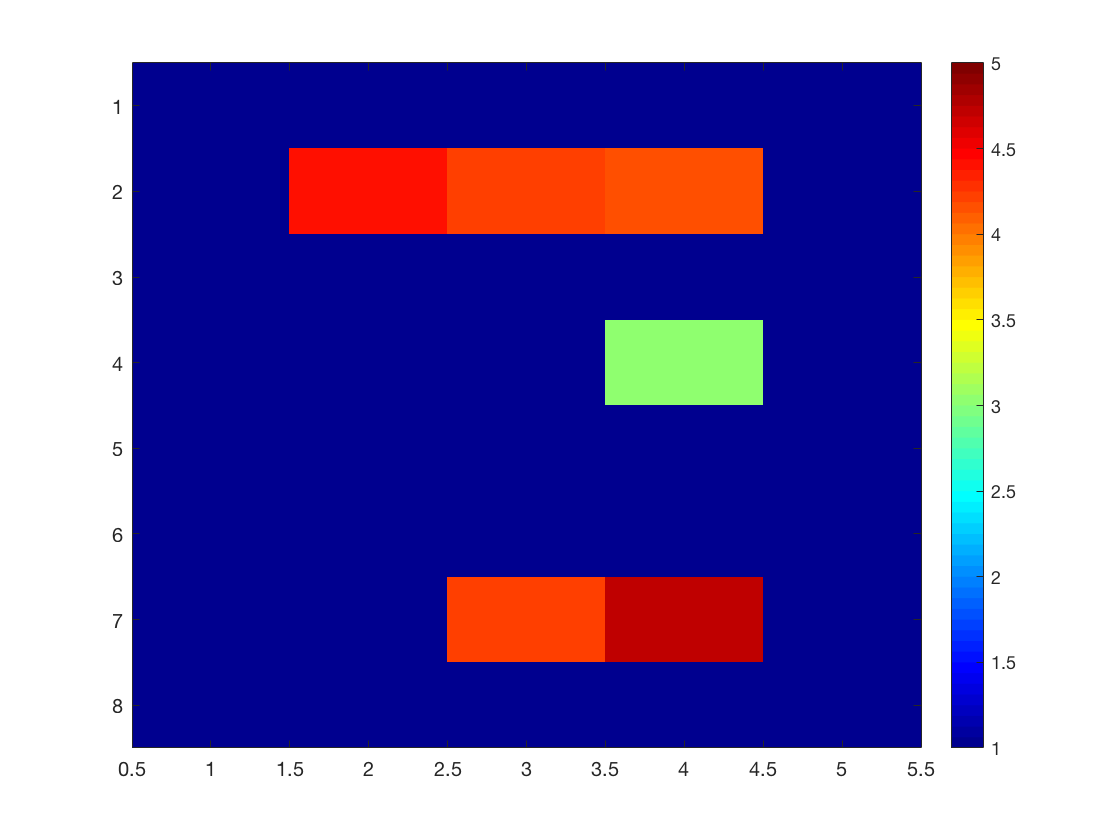

colormap('jet');
imagesc(mapValues, [1 5]); %range from 1-5
colorbar